## Import and organize data

% Read in data
data = readtable("Balloon Prelab Data 2020.xlsx");


% Remove unnecessary data
data.Var1 = [];
data(4:5, :) = [];

% Change variable names to be more user-friendly
newVarNames = {'BalloonNumber', 'BalloonMass', 'StringMass', 'AdditionalMass', 'PayloadMass', 'PILOTTemp', 'PILOTPressure', 'BalloonDiameter', 'MaxBalloonThickness', 'WaterHeightDisplacement', 'TankLength', 'TankWidth'};
data.Properties.VariableNames = newVarNames;

% Sort data by ascending balloon mass (to help with graphs)
% data = sortrows(data, 'BalloonMass');

% Convert various data types to number values
data.TankLength = str2num(cell2mat(data.TankLength));
data.WaterHeightDisplacement = [98.0, 105.0,96.0]';
data.BalloonDiameter = str2num(cell2mat(data.BalloonDiameter));
data.PILOTPressure = str2num(cell2mat(data.PILOTPressure));

data.PILOTTemp = str2num(cell2mat(data.PILOTTemp));

% Add new variables based on existing data
data.TankArea = data.TankLength .* data.TankWidth; % Tank area in in^2
data.TotalMass = data.BalloonMass + data.PayloadMass; % Tank mass in g
data.BalloonVolume = (0.0254 * data.TankArea) .* (data.WaterHeightDisplacement / 1000); % Balloon volume in m^3

% Display table
data

data = 3×15 table
    BalloonNumber    BalloonMass    StringMass    AdditionalMass    PayloadMass    PILOTTemp    PILOTPressure    BalloonDiameter    MaxBalloonThickness    WaterHeightDisplacement    TankLength    TankWidth    TankArea    TotalMass    BalloonVolume
    _____________    ___________    __________    ______________    ___________    _________    _____________    _______________    ___________________    _______________________    __________    _________    ________    _________    

## Create graph(s)

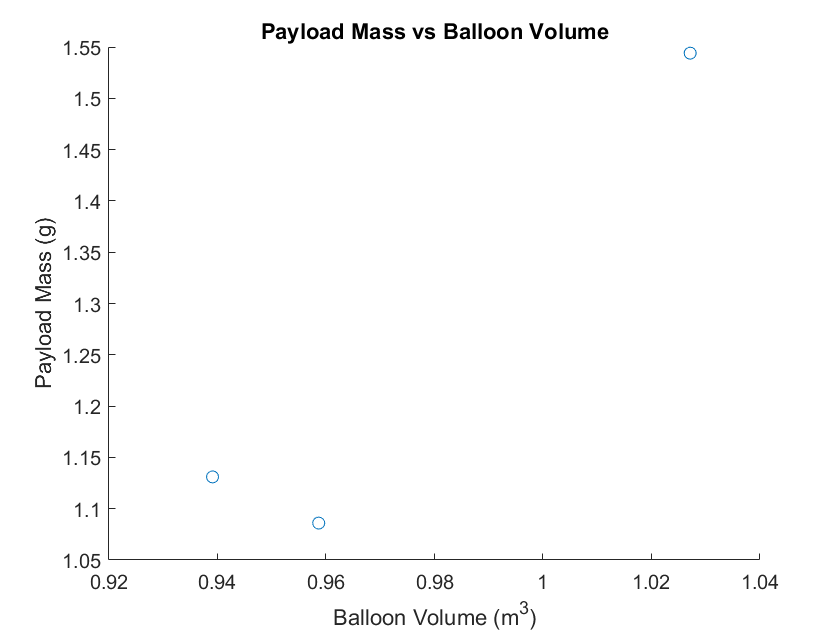

% Preliminary plot of payload mass vs balloon mass
    % I now realize that this is actually super irrelevant because the
    % balloon mass has nothing to do with how much weight it can hold we
    % need the volume
scatter(data.BalloonVolume, data.PayloadMass)
title("Payload Mass vs Balloon Volume");
xlabel("Balloon Volume (m^3)");
ylabel("Payload Mass (g)");% sdfjlksdf

## Experiment analysis

% Find force caused by gravity
forceGrav = data.TotalMass .* 9.81 % Force of gravity in m/s^2

forceGrav =   104.5256
  108.8616
  105.3888



% Find buoyancy force
%    F_B = rho_f * gravity * volume
%    rho_f = F_B / (gravity * volume)
forceBuoy = forceGrav % Buoyant force is equal to force of gravity when neutrally buoyant

forceBuoy =   104.5256
  108.8616
  105.3888


rho_f = forceBuoy ./ (9.8 .* data.BalloonVolume)

rho_f =    11.1259
   10.8149
   11.4515




% Estimate required mass of gas


% Use Ideal Gas Equation to estimate theoretical mass of gas (PV = nRT)